# `One Wheel Slip Control`

# `Traction control system TCS and Antilock Breaking systems ABS`

`Matlab & Simulink`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Vehicle Control Systems  | Ohio State University | 9/2022`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents`

`1. Introduction `

`2. Background `

`3. Base level Traction Control and Autilock Braking `

`4. Conversion to magic tire formula, aka the Pacejka model`

`5. Replacing the bang bang controller with a PID`

`6. WIP, varying friction `

`7. Conclusions and future work`

`8. Functions`

# `1.Introduction`

`    The objective of this document and accompanying matlab code and simulink models is to improve a given ABS And TCS simulation.`

# `2.Background `

`    Control of wheel slip is crucial because it has a direct relationship with the longitudinal and lateral tire forces that give control to the driver of a vehicle. The relationship between wheel slip and tire forces is nonlinear and can be approximated using various tire models, such as the Magic Tire Formula Model (BNP), the Nicolas-Comstock model, and the Modified Nicolas Comstock (MNC) model. These relationships and models have been explored in my previous work on tire models.`

`Wheel slippage is quantified by the Longitudinal Slip Percentage (S) of a wheel, which represents the amount of sliding occurring at the road-tire interface as a percentage or ratio. The slip is defined as follows:`

- `When Braking (-1 < S < 0): Wheel lockup or sliding occurs, with S calculated as (ω Re - Vx)/Vx, where ω is the angular velocity of the wheel, Re is the effective rolling radius of the tire, and Vx is the longitudinal velocity of the vehicle.`

- `During Traction Loss (0 < S < 1): The wheel rotates without translational motion, with S calculated as (ω Re - Vx)/(ω Re).`

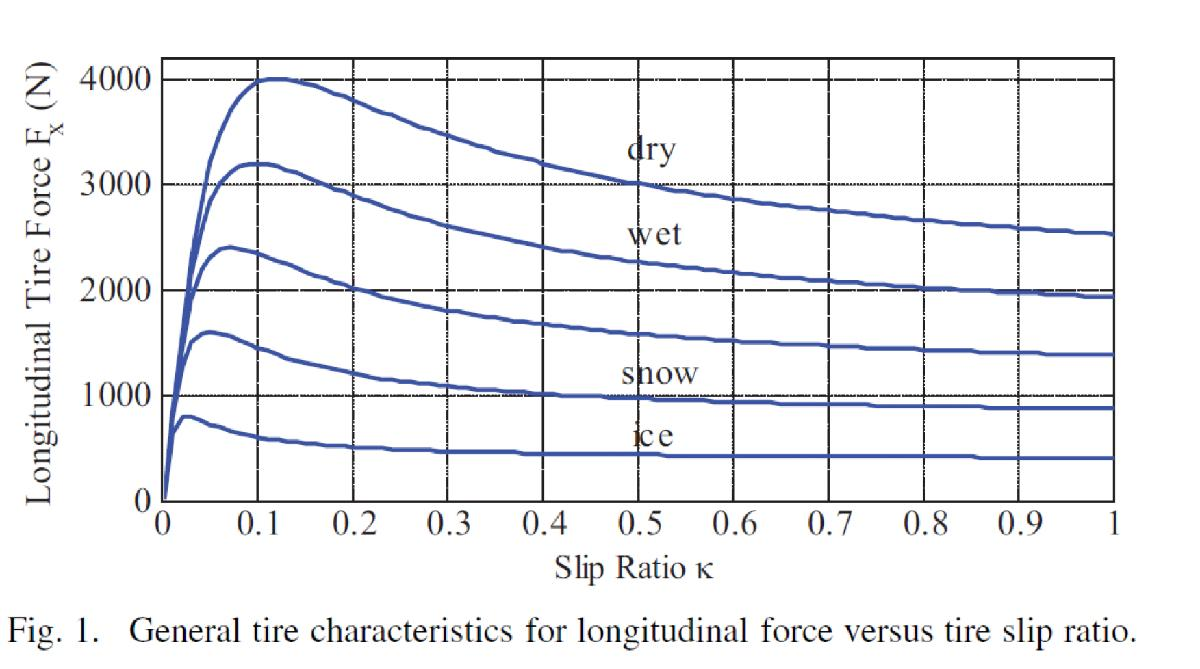

`An Anti-Lock Braking System (ABS) is used to control wheel slip during braking. It offers three primary benefits that enhance vehicle safety and performance. Firstly, ABS decreases the stopping distance of a vehicle during full braking, allowing drivers to stop more quickly in emergency situations. Secondly, it helps maintain steering control while fully braking, enabling drivers to maneuver around obstacles even during hard braking. Lastly, ABS helps avoid rotational instability, also known as spinouts, that may occur when road conditions vary between the left and right sides of the vehicle. Spinouts can be particularly dangerous, and ABS assists in preventing them by modulating brake pressure to individual wheels. I reccomend watching the following video: `[`https://youtu.be/98DXe3uKwfc`](https://youtu.be/98DXe3uKwfc)

`A Traction Control System (TCS) is another form of wheel slip control, specifically designed to enhance traction during excess throttle. Unlike ABS, which is used during braking, TCS applies only to the drive wheels and aims to prevent wheel spin during acceleration. TCS reduces unnecessary tire wear caused by excessive spinning, improves vehicle acceleration on slippery surfaces, and increases overall vehicle control. `

`Commonly, TCS is implemented as follows: At low speeds, the TCS system applies braking to a spinning wheel, thereby redistributing torque and sending more power to the other wheels with better grip. At higher speeds, the TCS system controls engine output by throttling the fuel injection or adjusting the ignition angle until all wheels regain traction. Through these mechanisms, TCS enhances the driving experience and ensures better control of the vehicle in a variety of road conditions.`

 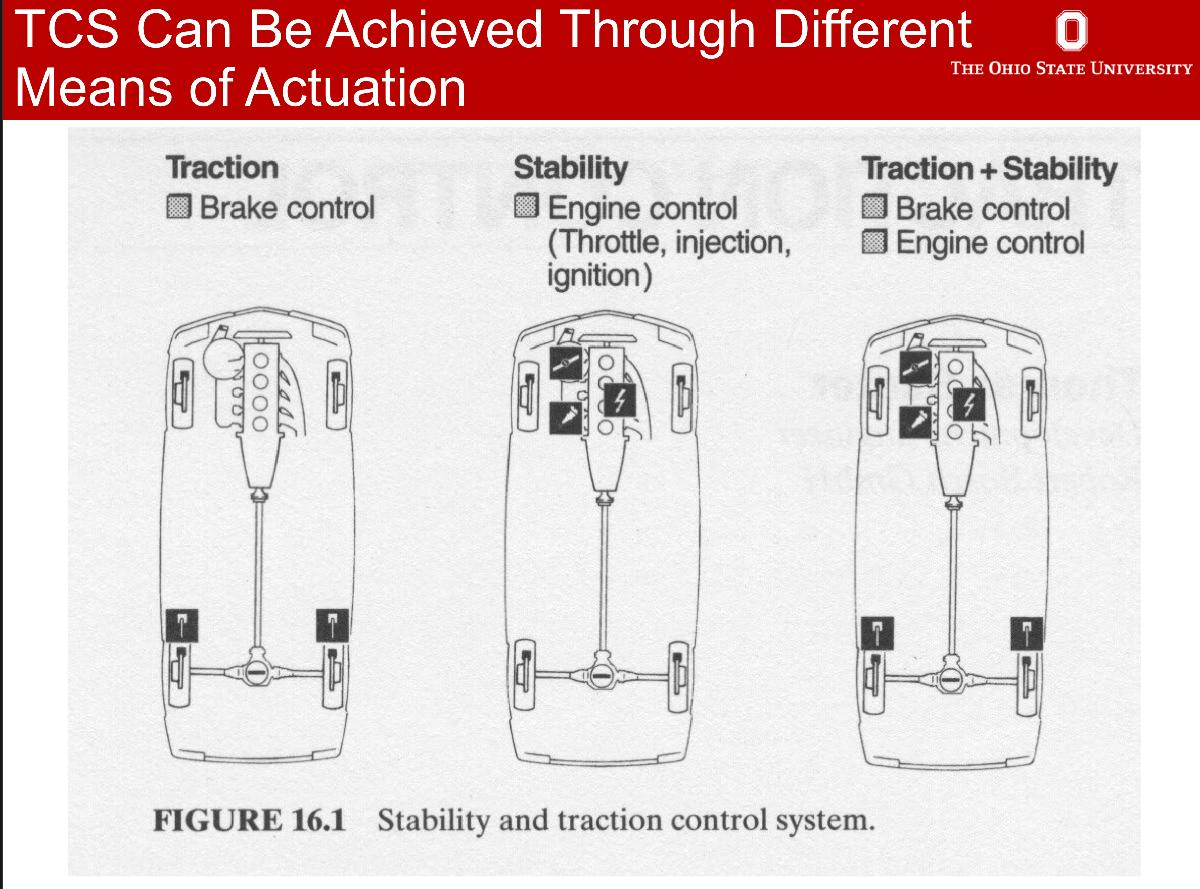

# 3a.Original ABS Model

Beggining from a model provided through the [Anti-Lock Braking System Matlab Demonstration](https://www.mathworks.com/help/simulink/slref/modeling-an-anti-lock-braking-system.html)

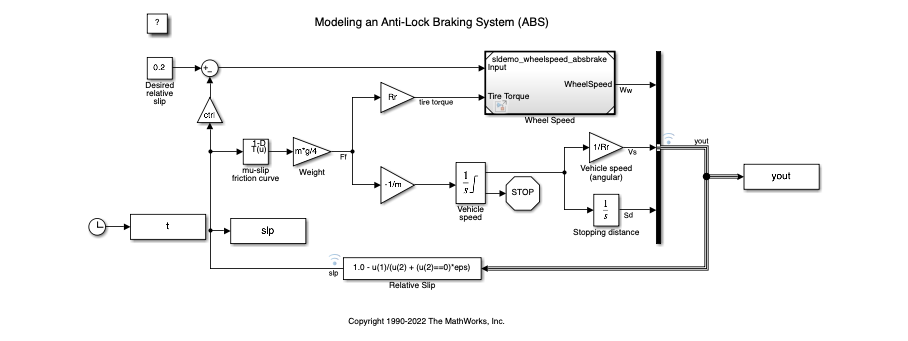

Lets run the model, once with the ABS on and once with the ABS off and plot the results

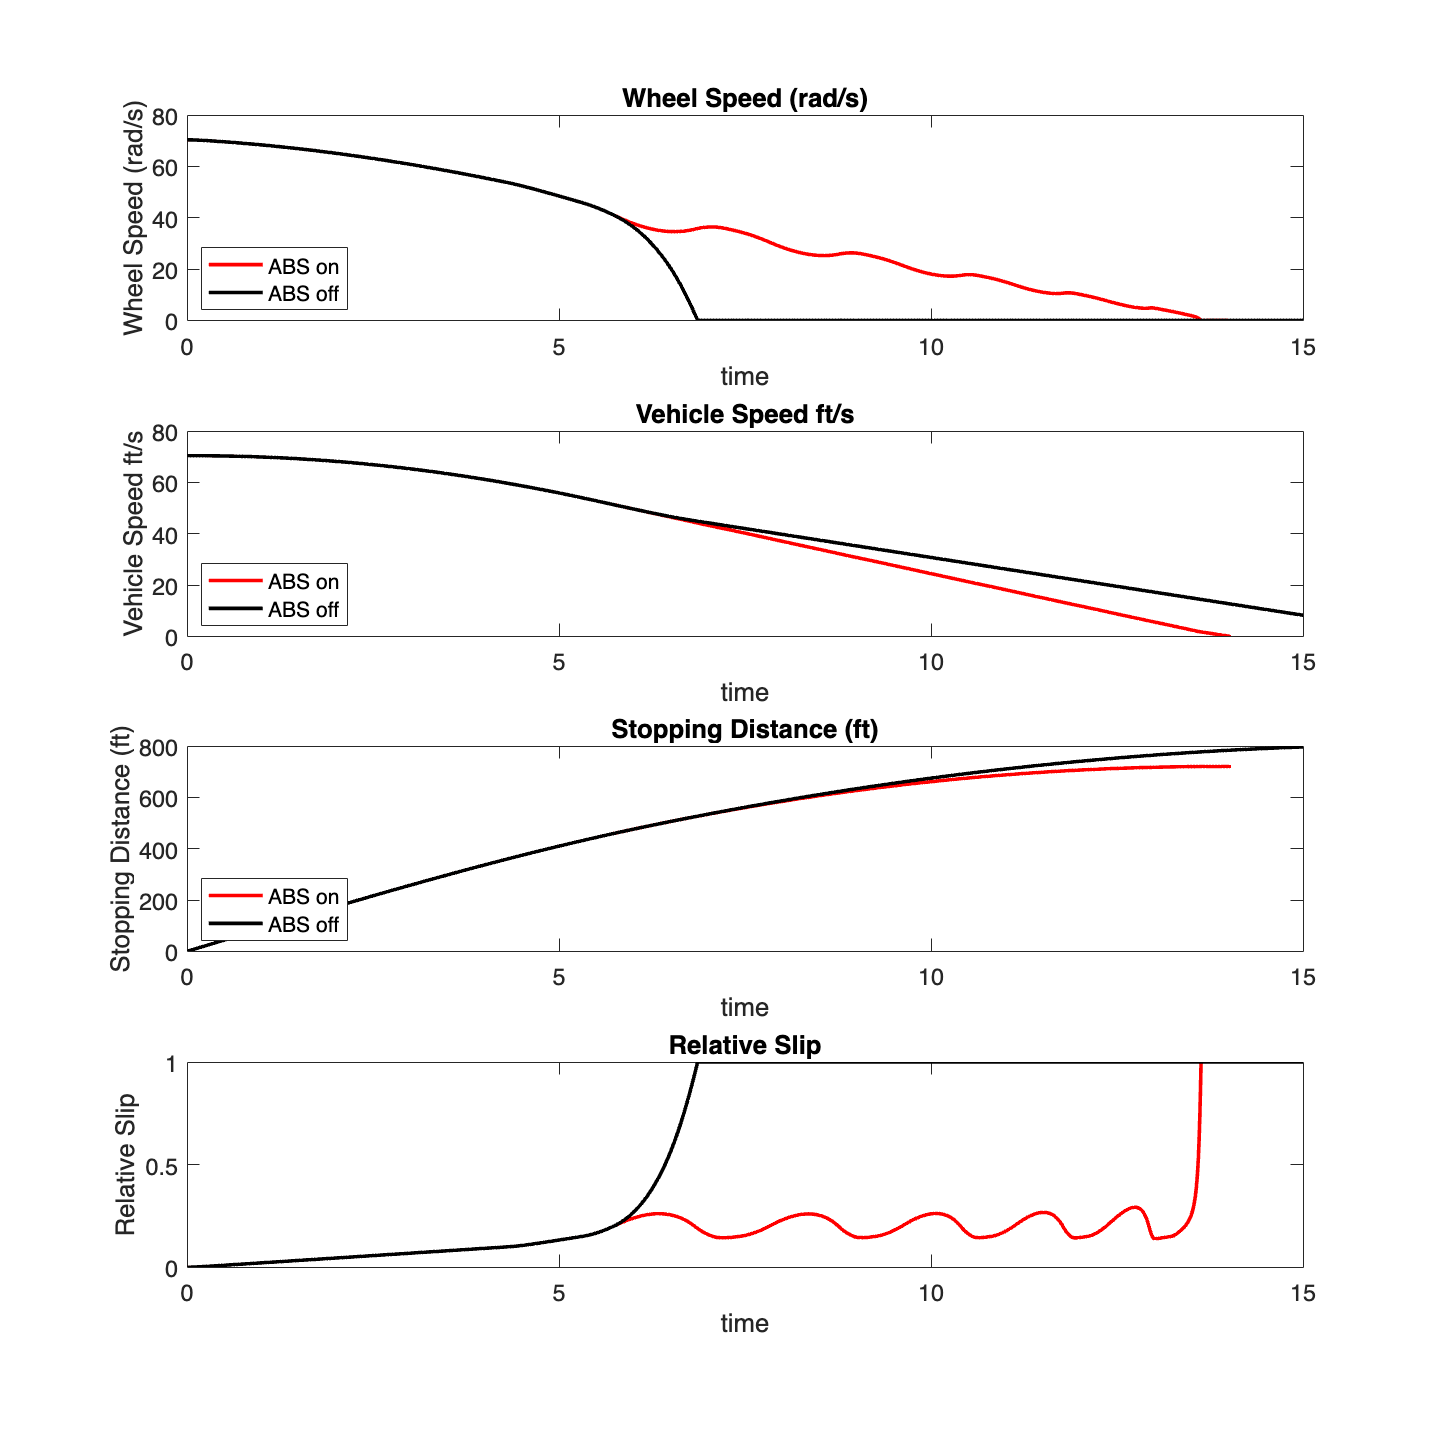

clc; clear; close all;

%outputs variables from sim are lumped into yout, which contains 
   % Ww Vehicle Speed
   % Vs angular wheel speed
   % Sd Stopping Distance

% get parameters and models 
addpath("UnalteredModels/"),load('OneWheelABS.mat') % the necessary models and parameters

% Sim ABS on
ctrl = 1;
sim('OneWheelABS.slx')
P = [yout]; t1 = t; slp1 = slp;

% Sim ABS off
ctrl = 0;
sim('OneWheelABS.slx')
P2 = [yout]; t2 = t; slp2 = slp;

ynames=["Wheel Speed (rad/s)","Vehicle Speed ft/s", "Stopping Distance (ft)" ,"Relative Slip"];

% Plotting 
for i = 1:1:3
    % ABS on
    subplot(4,1,i)
    plot(t1,P(:,i),'Linewidth',2,'Color',[1 0 0])
    hold on;

    % ABS off
    plot(t2,P2(:,i),'Linewidth',2,'Color',[0 0 0])

    % plot labels 
    legend('ABS on','ABS off'), xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',13),legend('Location', 'southwest');

end 
% slip 
subplot(4,1,4), plot(slp1,'Linewidth',2,'Color',[1 0 0]), hold on
plot(slp2,'Linewidth',2,'Color',[0 0 0]), xlabel('time'), ylabel(ynames(4)), title(ynames(4))
set(gcf, 'Position', [0 0 1000 1000]), set(gca,'FontSize',13)

ABSPo = P;
ABSto = t1;
slpo = slp1;

`The ABS given in this model improves stopping distance and stopping time compared to a sliding stop`

# 3b.Original TCS Model

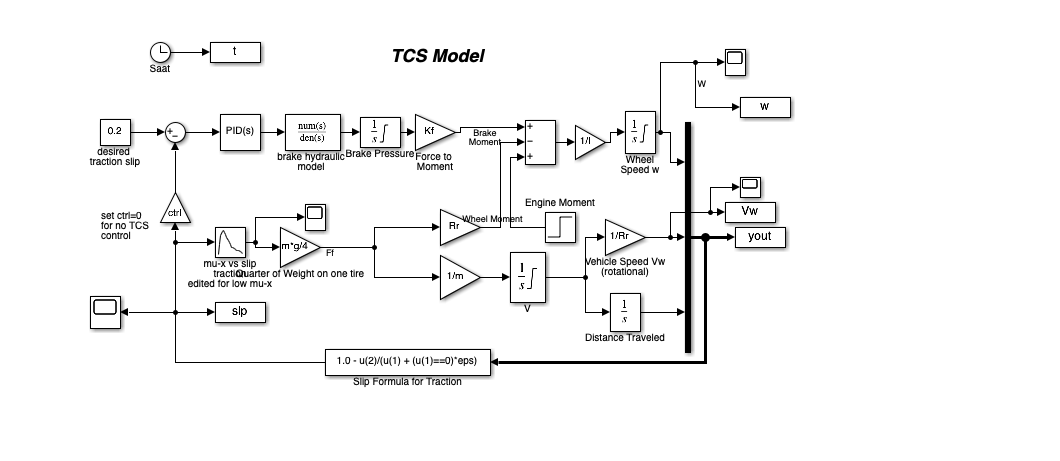

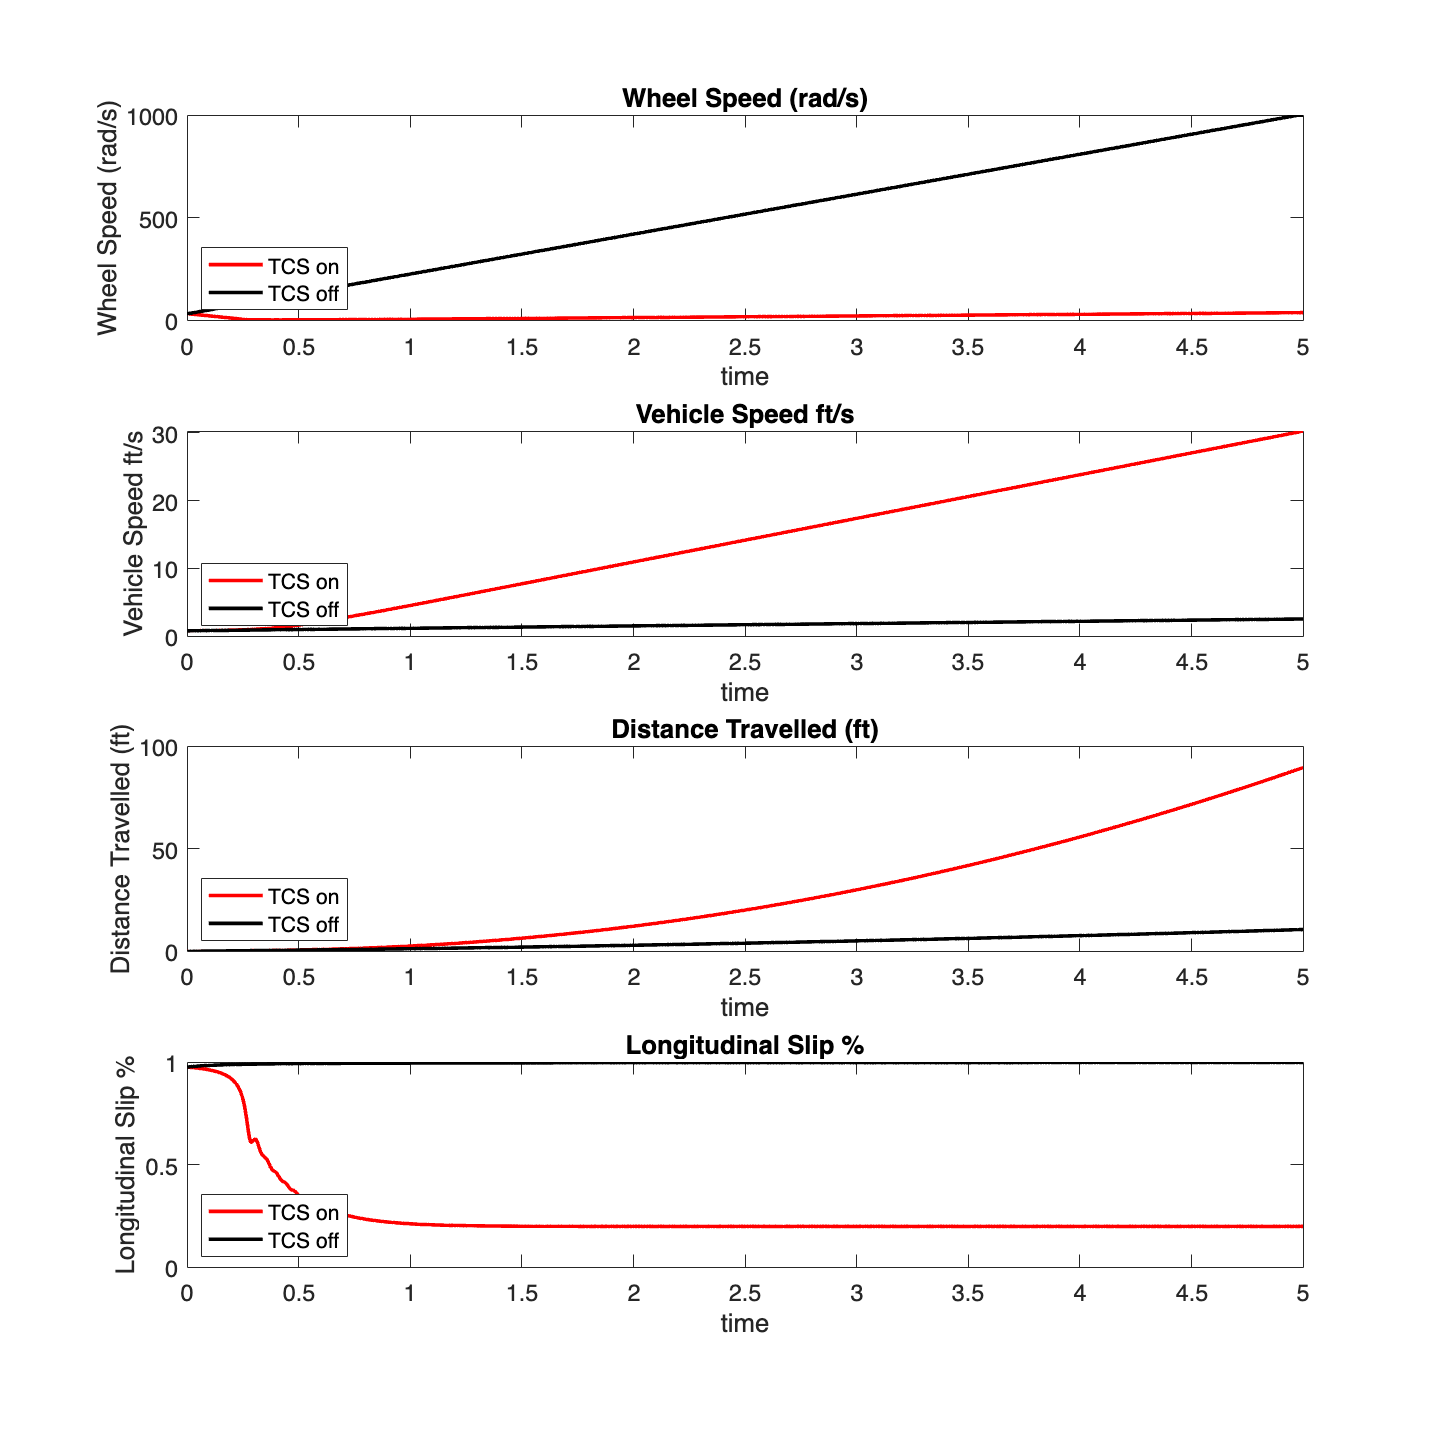


%outputs variables are the following: 
    %w  %linear wheel speed
    % Vw %wheel velocity angular
    % yout %distance travelled?
    % slp %slip!
    % t time 

% sim TCS on 
load('OneWheelTCS.mat')
sim('OneWheelTCS.slx')
P = [yout slp];  t1 = t;

% sim TCS off 
ctrl = 0;
sim('OneWheelTCS.slx')
P2 = [yout slp]; t2 = t;

ynames=["Wheel Speed (rad/s)","Vehicle Speed ft/s", "Distance Travelled (ft)","Longitudinal Slip %"];

% Plotting 
figure()
for i = 1:1:4
    % ABS on
    subplot(4,1,i)
    plot(t1,P(:,i),'Linewidth',2,'Color',[1 0 0])
    hold on;

    % ABS off
    plot(t2,P2(:,i),'Linewidth',2,'Color',[0 0 0])

    % plot labels 
    legend('TCS on','TCS off'), xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',13),legend('Location', 'southwest');

end 
set(gcf, 'Position', [0 0 1000 1000])

TCSPo = P;
TCSto = t1;

# 4.Implement the magic tire formula in ABS and TCS models

replacing this area of the block diagram will eliminate the usage of the mu slip curve/table and calculate longitudinal force through the magic tire formula which was built in simulink: 

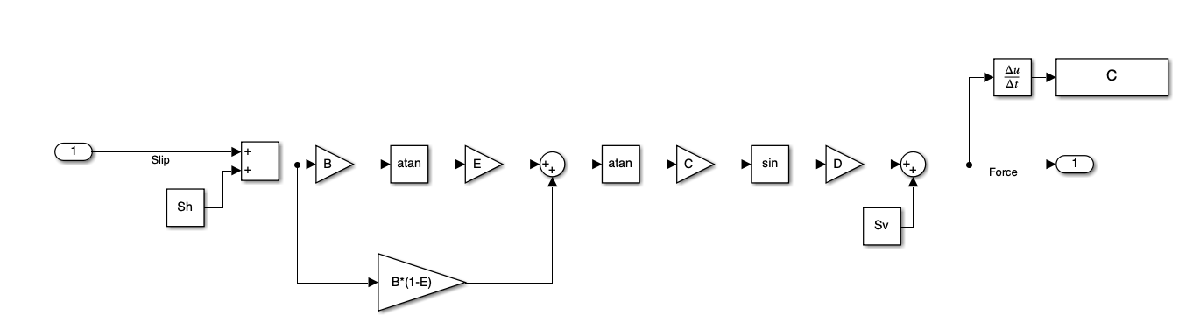

In the past I made a magic tire formula function, but I had trouble converting it,  so simulink was used instead. 

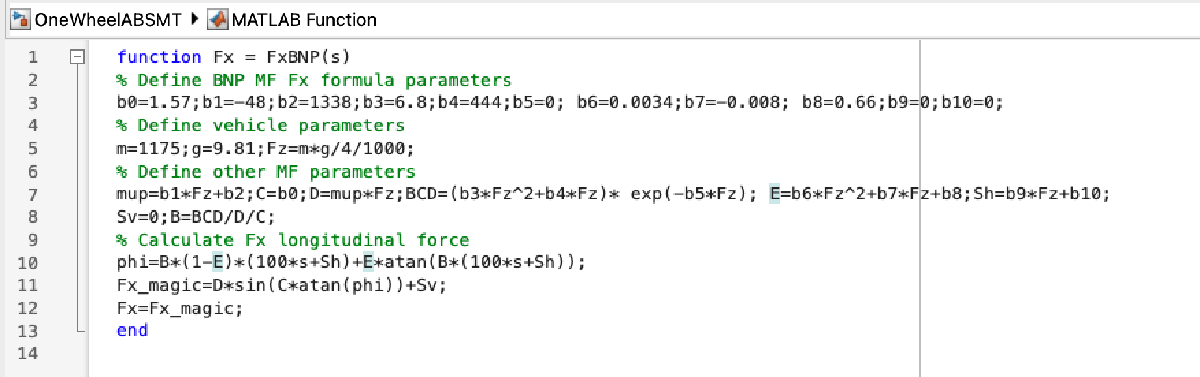

The area to be replaced in both diagrams: 

TCS 

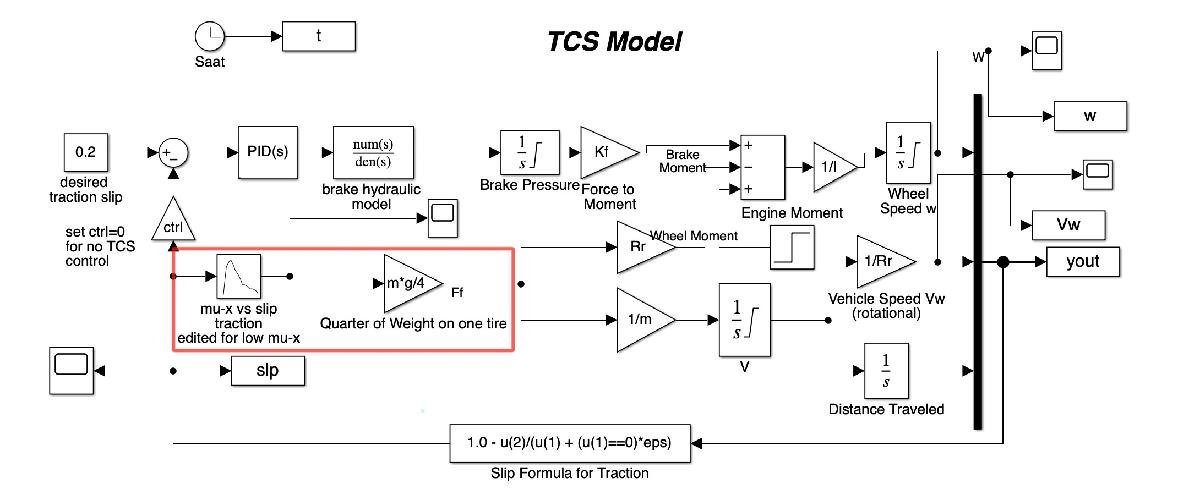

this area takes s as an input, gives mu, the friction coefficient, and then multiplies by m*g/4 which is the normal force on one tire. therefore emulating mu*N = friction. 

ABS

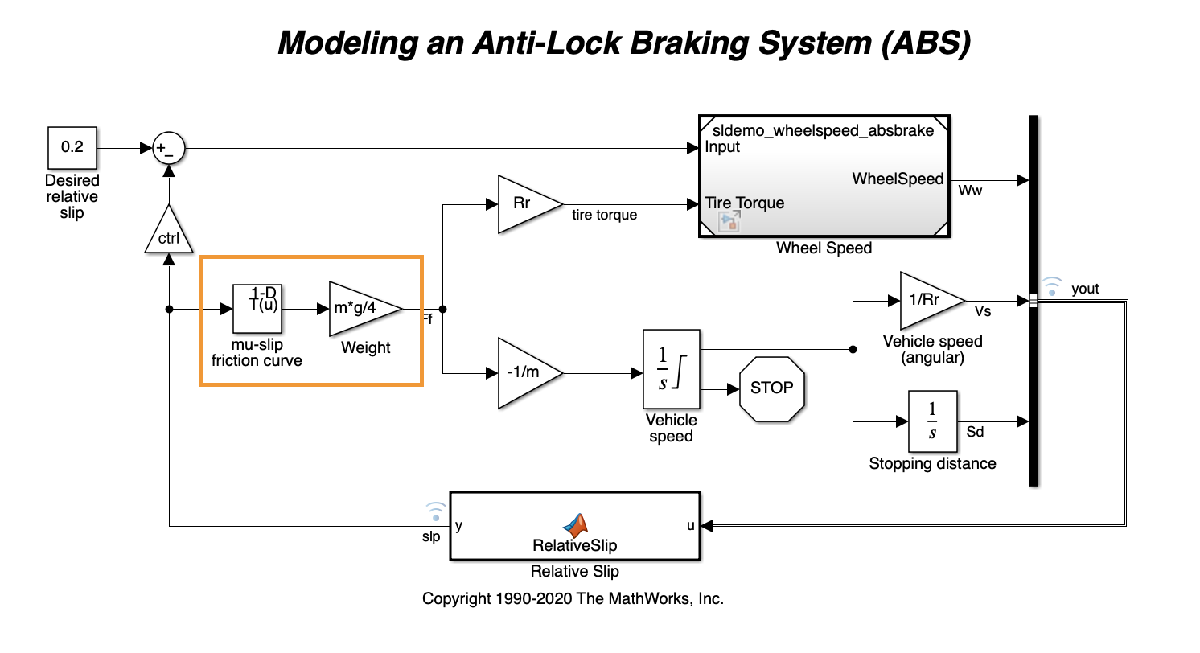

# 4a.ABS, magic tire formula  

% Magic tire parameters 
b0=1.57;b1=-48;b2=1338;b3=6.8;b4=444;b5=0; b6=0.0034;b7=-0.008; b8=0.66;b9=0;b10=0; Sh=0;
% Define vehicle parameters 
m=1175;g=9.81;Fz=m*g/4/1000;
% Define other MF parameters 
mup=b1*Fz+b2;C=b0;D=mup*Fz;BCD=(b3*Fz^2+b4*Fz)* exp(-b5*Fz); E=b6*Fz^2+b7*Fz+b8;Sh=b9*Fz+b10;Sv=0;B=BCD/D/C;

% where the new models reside 
rmpath("UnalteredModels/"),addpath("AlteredModels1/")
load('OneWheelABS.mat'),C=b0;
sim('OneWheelABSMT.slx')

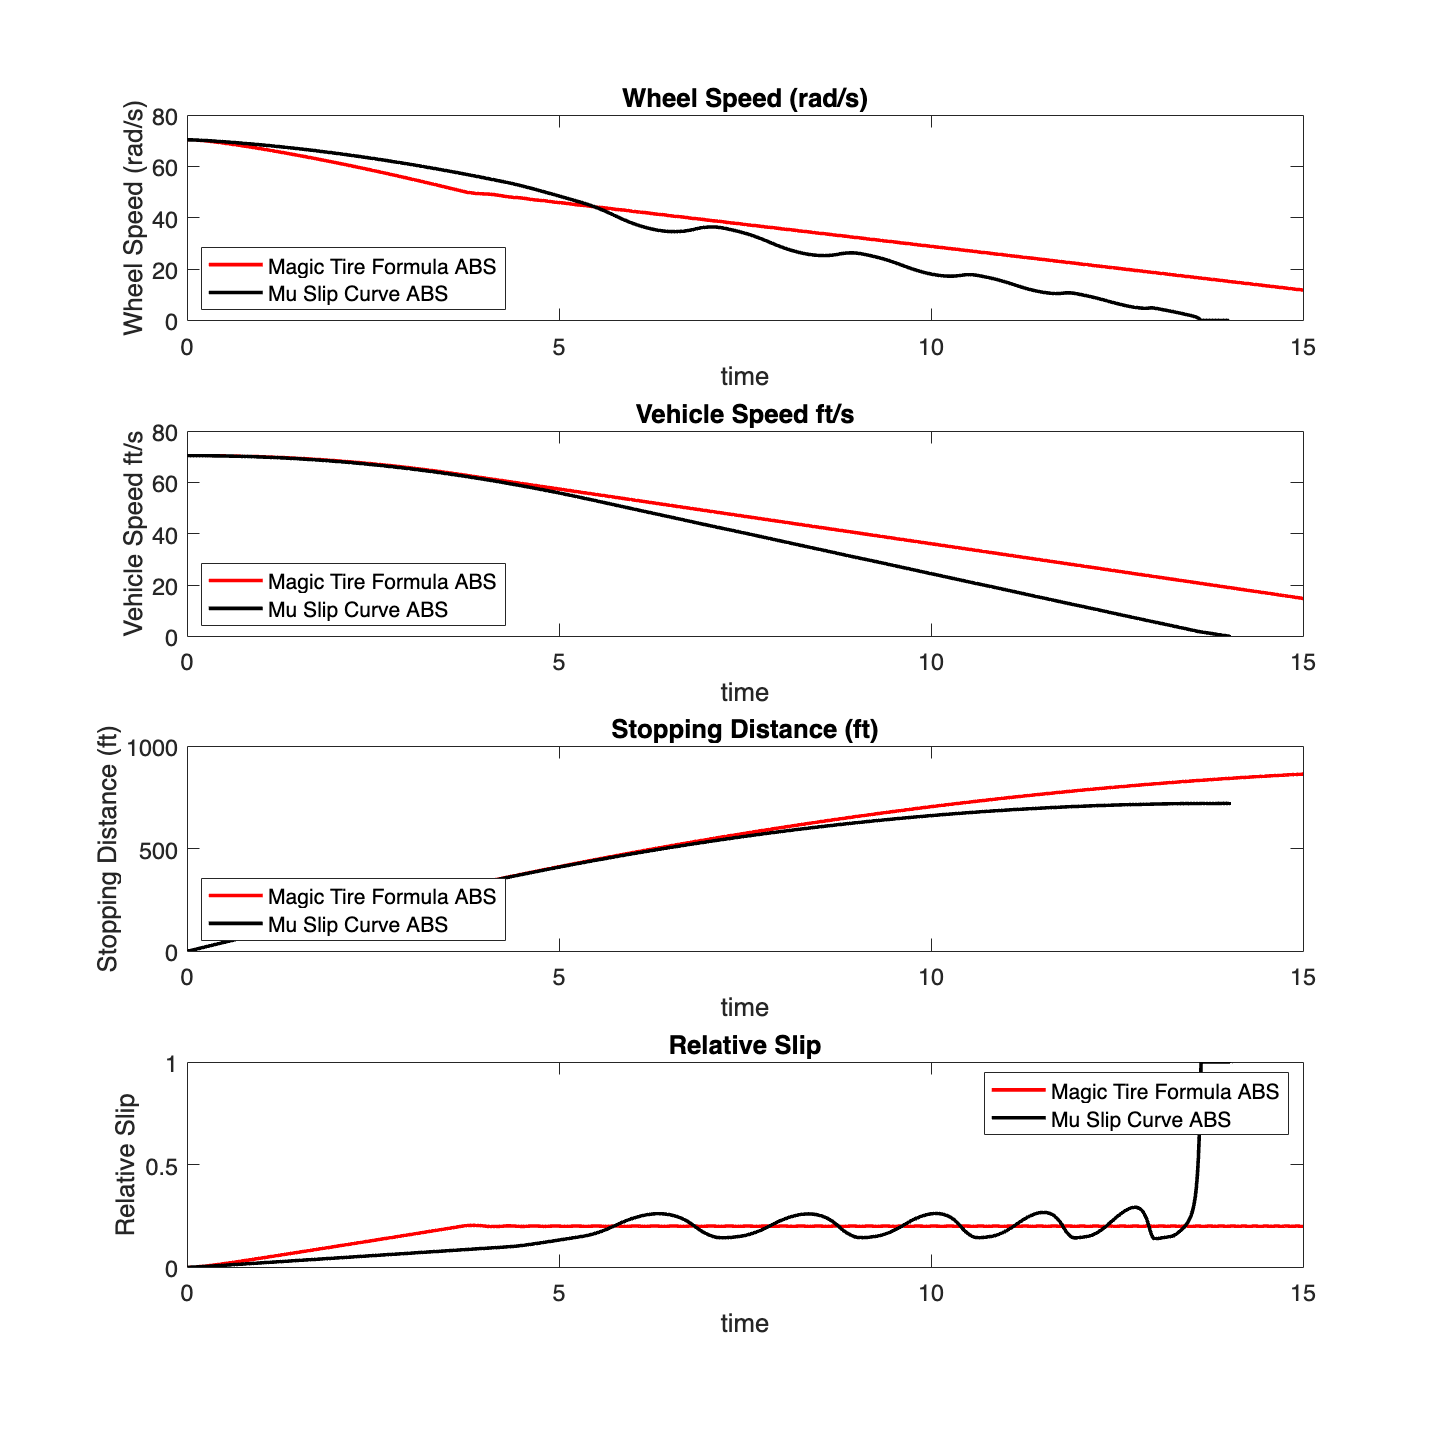

ynames=["Wheel Speed (rad/s)","Vehicle Speed ft/s", "Stopping Distance (ft)" ,"Relative Slip"];
P = [yout]; %plots
figure(3)

% Plotting 
figure(), close all
for i = 1:1:3
    % ABS on
    subplot(4,1,i)
    plot(t,P(:,i),'Linewidth',2,'Color',[1 0 0])
    hold on;

    % mu slip curve ABS
    plot(ABSto,ABSPo(:,i),'Linewidth',2,'Color',[0 0 0])

    % plot labels 
    legend('Magic Tire Formula ABS','Mu Slip Curve ABS'), xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',13),legend('Location', 'southwest');

end 
% slip 
subplot(4,1,4), plot(slp,'Linewidth',2,'Color',[1 0 0]), hold on
plot(slpo,'Linewidth',2,'Color',[0 0 0]), xlabel('time'), ylabel(ynames(4)), title(ynames(4)),legend('Magic Tire Formula ABS','Mu Slip Curve ABS')
set(gcf, 'Position', [0 0 1000 1000]), set(gca,'FontSize',13)

slpabs=slp;
ABSPmt = P;
ABStmt = t;
slpabsmt = slp;

The magic tire formula decreased performance relative to the base model, but is it more accurate? 

# 4b.TCS, magic tire formula 

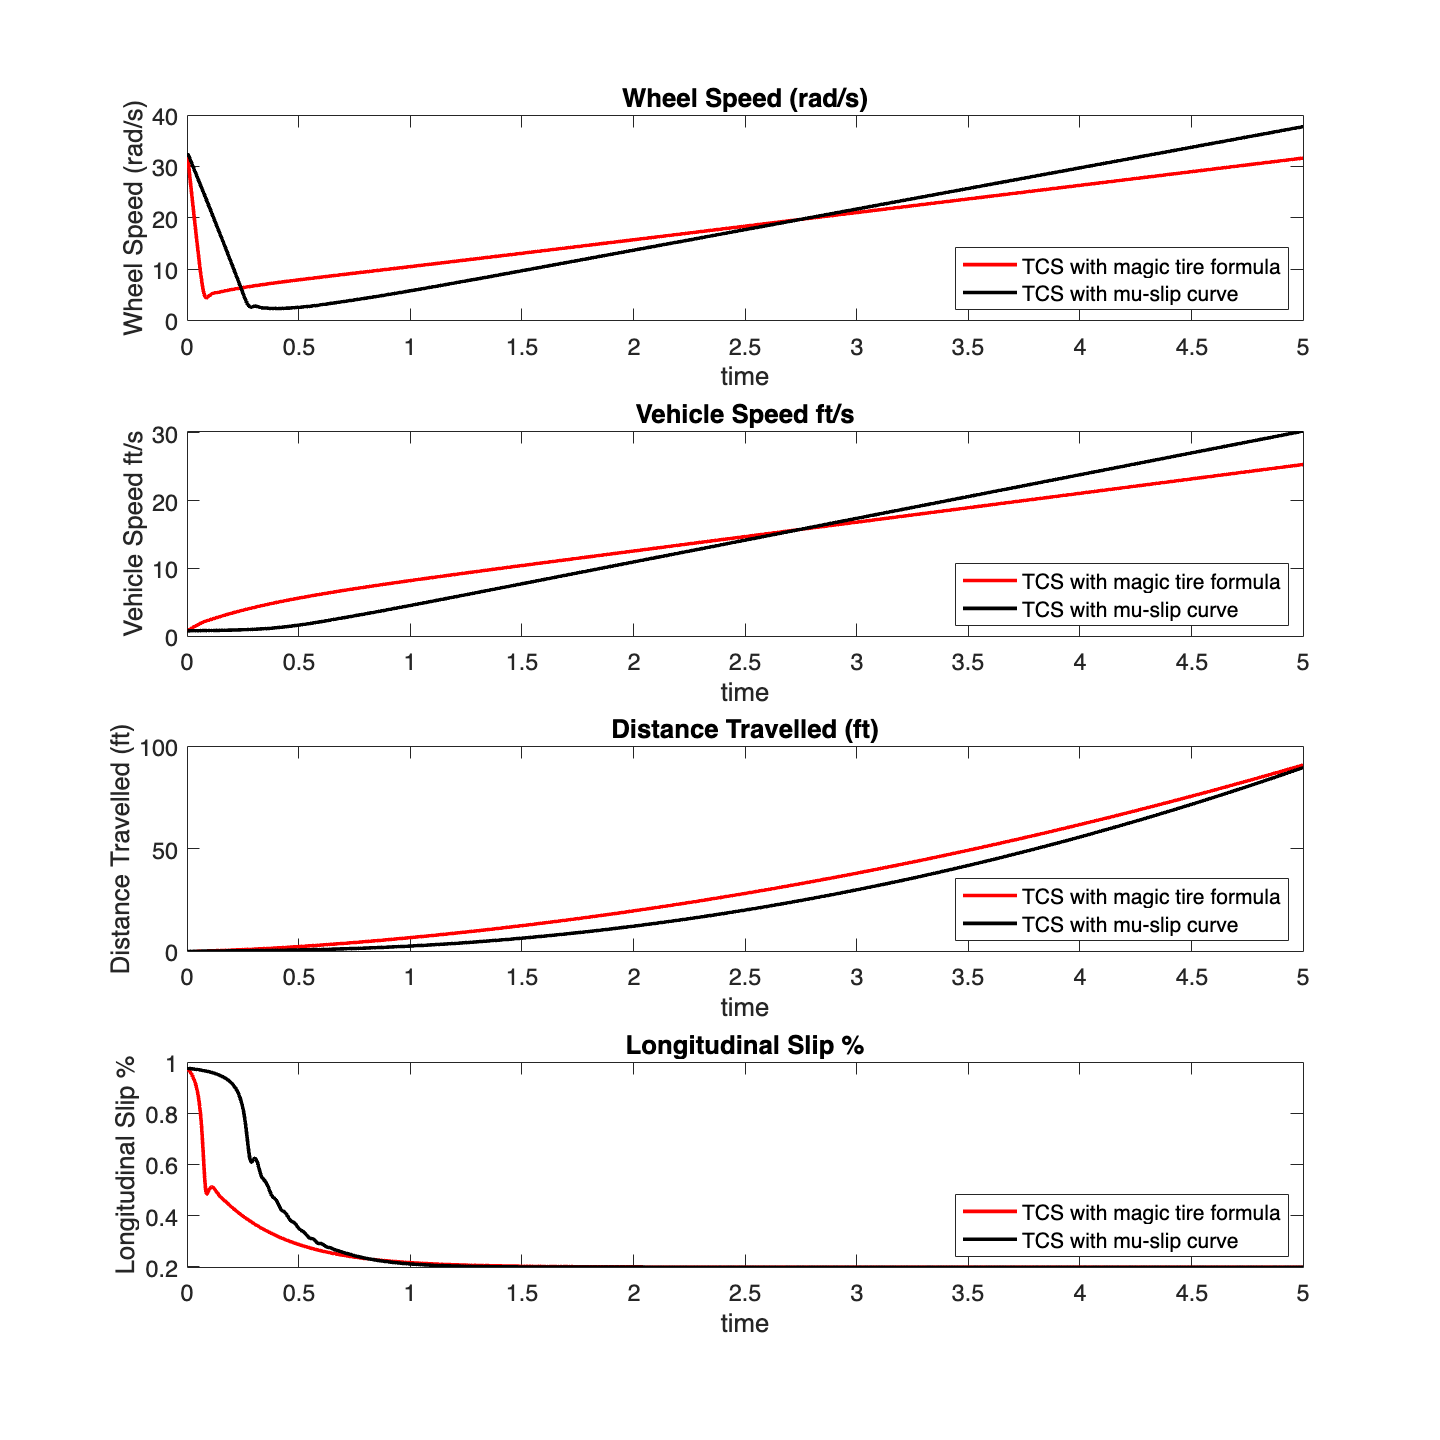

load('OneWheelTCS.mat'),sim("OneWheelTCSMT.slx")
P = [yout slp]; %plots

ynames=["Wheel Speed (rad/s)","Vehicle Speed ft/s", "Distance Travelled (ft)","Longitudinal Slip %"];

% Plotting 
figure()
for i = 1:1:4
    % magic tire formula TCS
    subplot(4,1,i)
    plot(t,P(:,i),'Linewidth',2,'Color',[1 0 0])
    hold on;

    % original TCS
    plot(TCSto,TCSPo(:,i),'Linewidth',2,'Color',[0 0 0])

    % plot labels 
    legend('TCS with magic tire formula','TCS with mu-slip curve'), xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',13),legend('Location', 'southeast');

end 
set(gcf, 'Position', [0 0 1000 1000])

`Interestingly, the magic tire formula seems to increase initial performance here. `

slptcs=slp;
TCSPmt = P;
TCStmt = t;

`One other area these models can be modified to potentially increase performance is changing the controller`

# 5.Controller Redesign

A PID Simulink Block will be used to replace the bang bang controller which will then be tuned 

Several Automatic tuning methods were attemped. 

manual tuning worked best where the three gains started at Kp=100, Ki=2, Kd=100 and then adjusted manually to the values they currently reside at. 

# 5a.ABS with PID and magic tire formula 

rmpath("AlteredModels1/"),addpath("AlteredModels2/")

load('OneWheelABS.mat')
sim('OneWheelABSPID.slx')

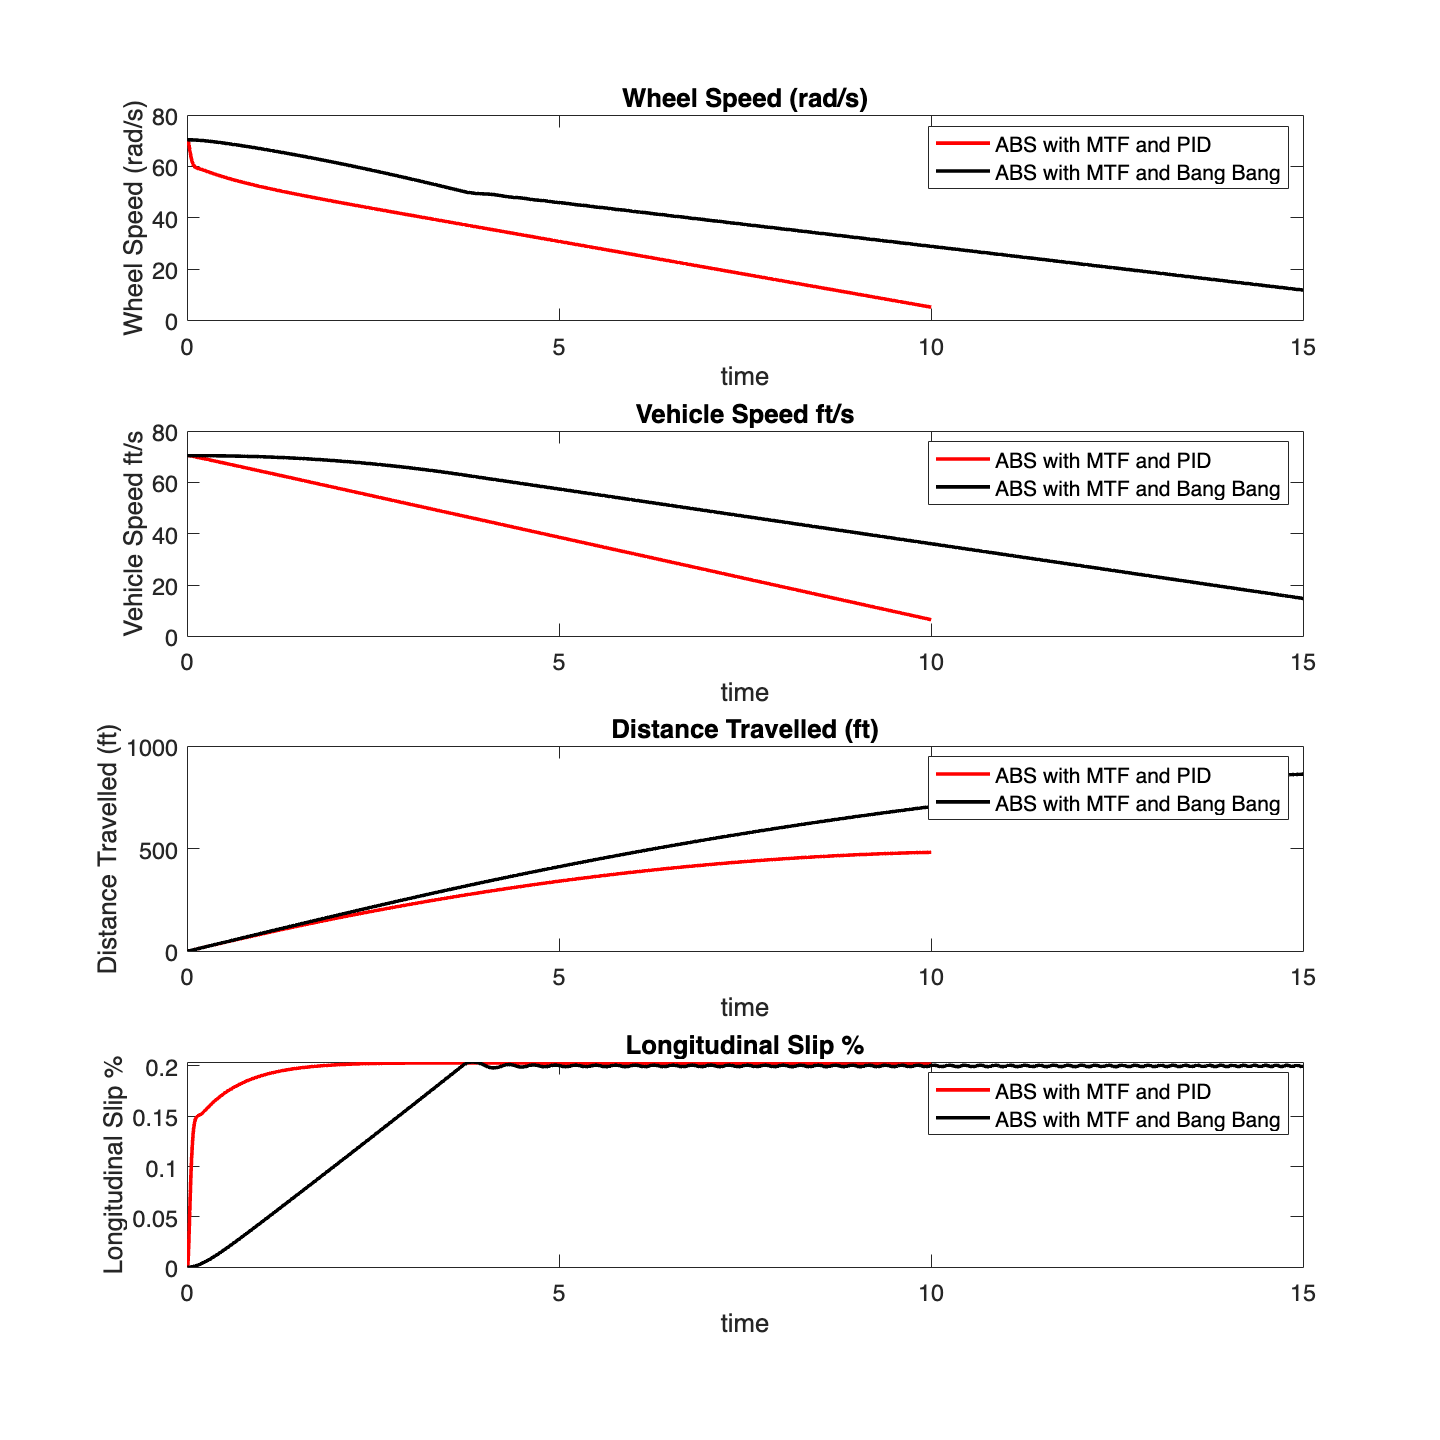

P = [yout]; 
figure
ynames=["Wheel Speed (rad/s)","Vehicle Speed ft/s", "Distance Travelled (ft)","Longitudinal Slip %"];

% Plotting 
figure()
for i = 1:1:3
    % magic tire formula TCS with PID
    subplot(4,1,i)
    plot(t,P(:,i),'Linewidth',2,'Color',[1 0 0])
    hold on;

    % magic tire formula TCS with bang bang
    plot(ABStmt,ABSPmt(:,i),'Linewidth',2,'Color',[0 0 0])

    % plot labels 
    legend('ABS with MTF and PID','ABS with MTF and Bang Bang'), xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',13),legend('Location', 'northeast');
end 
% slip 
subplot(4,1,4), plot(slpabspid,'Linewidth',2,'Color',[1 0 0]), hold on
plot(slpabsmt,'Linewidth',2,'Color',[0 0 0]), xlabel('time'), ylabel(ynames(4)), title(ynames(4)),legend('ABS with MTF and PID','ABS with MTF and Bang Bang')
set(gcf, 'Position', [0 0 1000 1000]), set(gca,'FontSize',13)

set(gcf, 'Position', [0 0 1000 1000])

`The performance of the PID ABS system is improved over the bang bang controller, both with the magic tire formula. `

# 5b.TCS with PID and magic tire formula

load('OneWheelTCS.mat'),sim("OneWheelTCSPID.slx")

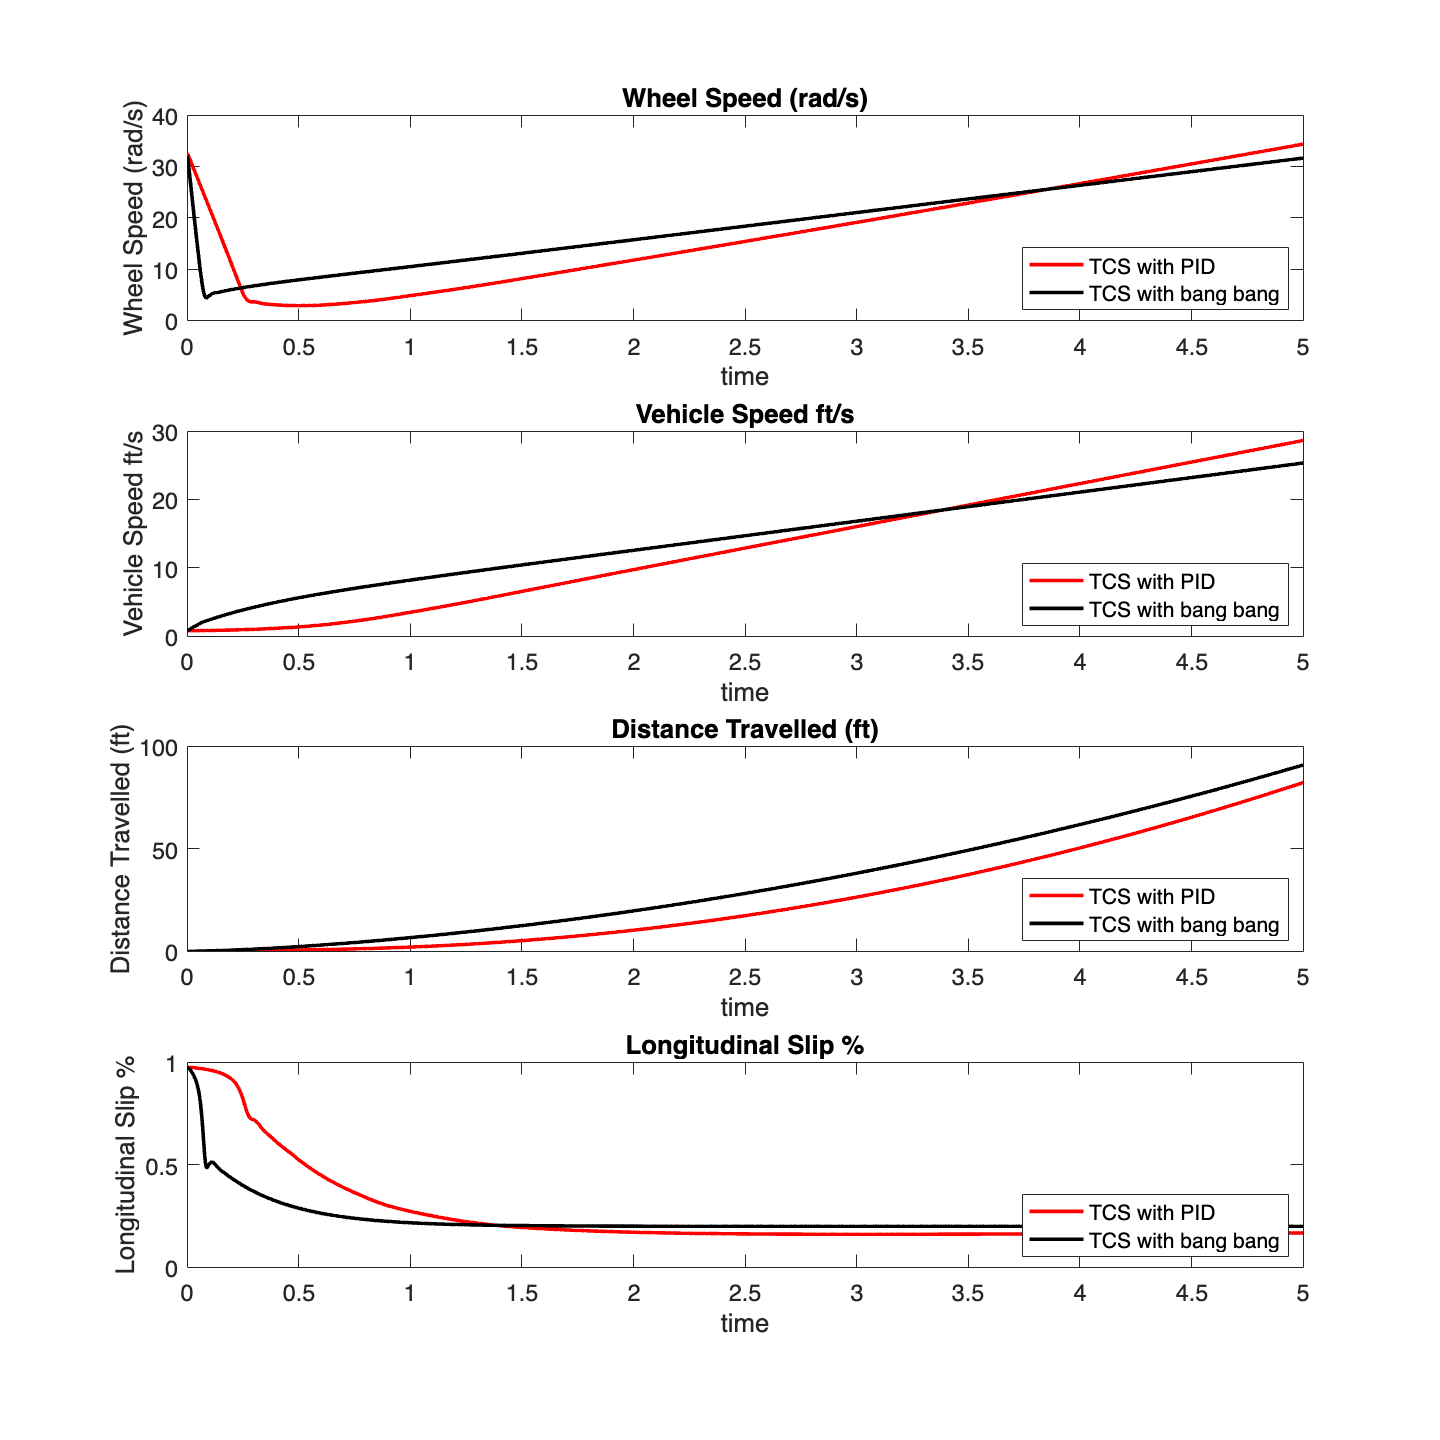

P = [yout slptcspid]; %plots

ynames=["Wheel Speed (rad/s)","Vehicle Speed ft/s", "Distance Travelled (ft)","Longitudinal Slip %"];

% Plotting 
figure()
for i = 1:1:4
    % magic tire formula TCS with PID
    subplot(4,1,i)
    plot(t,P(:,i),'Linewidth',2,'Color',[1 0 0])
    hold on;

    % magic tire formula TCS with bang bang
    plot(TCStmt,TCSPmt(:,i),'Linewidth',2,'Color',[0 0 0])

    % plot labels 
    legend('TCS with PID','TCS with bang bang'), xlabel('time'), ylabel(ynames(i)), title(ynames(i)), set(gca,'FontSize',13),legend('Location', 'southeast');

end 
set(gcf, 'Position', [0 0 1000 1000])

`The performance for TCS has decreased, furhter tuning is likely needed.`

# 6. Adding a gear ratio and shaft stiffness

# 7. Varying friction, WIP 

## Part 3 (and part 5)

Simulation study of ABS and TCS on icy or wet road by lowering friction 

(by multipying the input table of MU's to be lower)

ABS first 

clc; clear; close all;
rmpath("AlteredModels2/"),addpath("AlteredModels3/")

load('OneWheelABS.mat')
mu = mu*0.5;
sim('OneWheelABSss.slx')

ynames=["Vehicle Speed","Angular Wheel Speed","Stopping Distance","Slip %"];
P = [yout]; %plots
disp('Low Friction ABS Model Outputs'),figure(7)

Low Friction ABS Model Outputs


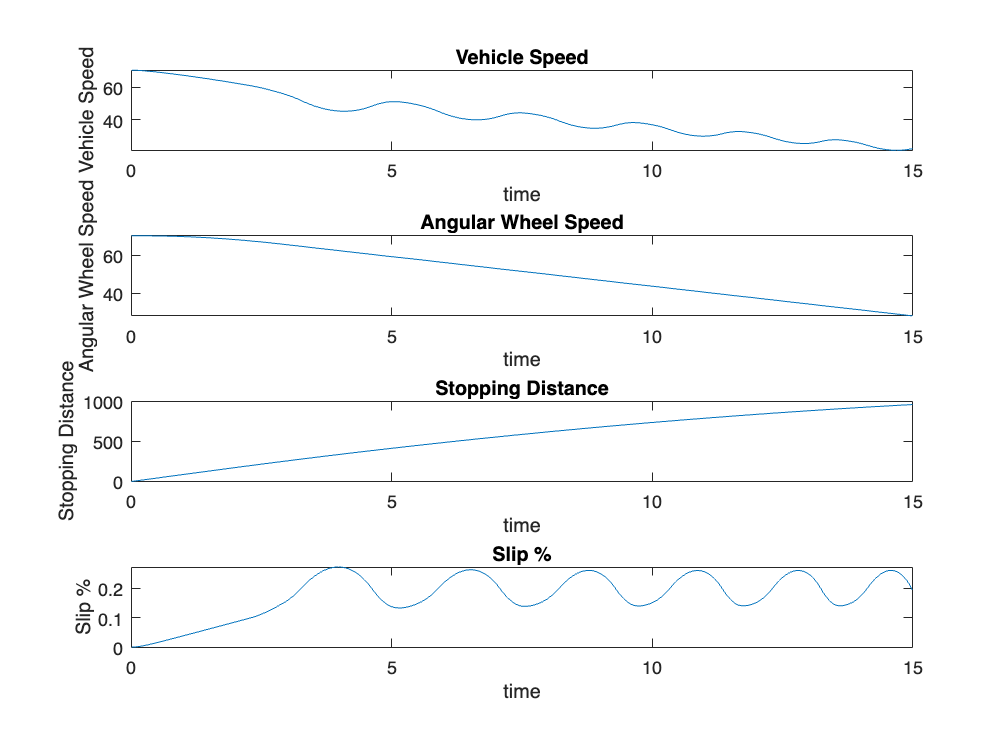

end of ABS model with Low Friction


for i = 1:1:3
    subplot(4,1,i)
    plot(t,P(:,i))
    xlabel('time')
    ylabel(ynames(i))
    title(ynames(i))
end 
subplot(4,1,4)
plot(slp),xlabel('time'),ylabel(ynames(4)),title(ynames(4))

TCS Next

load('OneWheelTCS.mat')
mu = mu*.5;
sim("OneWheelTCSss.slx")

ynames=["Vehicle Speed","Angular Wheel Speed","Distance Travelled","Longitudinal Slip %"];
P = [yout slp]; %plots
disp('Low Friction TCS outputs'),figure(8)

Low Friction TCS outputs


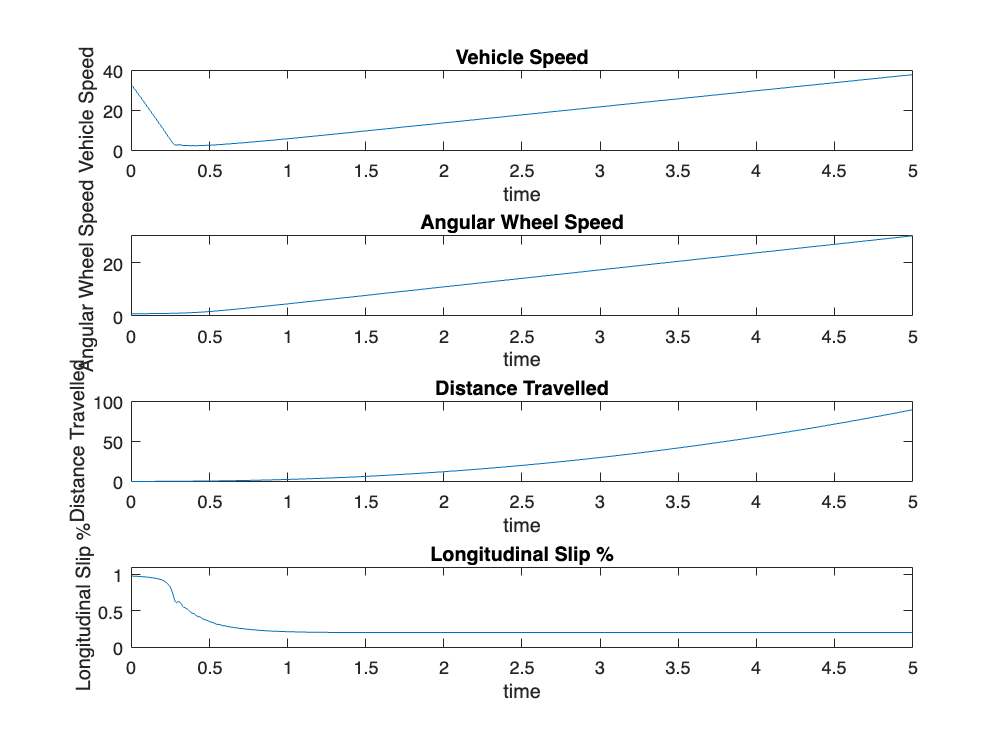

for i = 1:1:4
    subplot(4,1,i)
    plot(t,P(:,i))
    xlabel('time'),ylabel(ynames(i)),title(ynames(i))
end 
limits = [0 5 0 1.1];
axis(limits)

clc; clear; close all;
load('OneWheelTCS.mat')
sim('OneWheelTCStarget.slx')

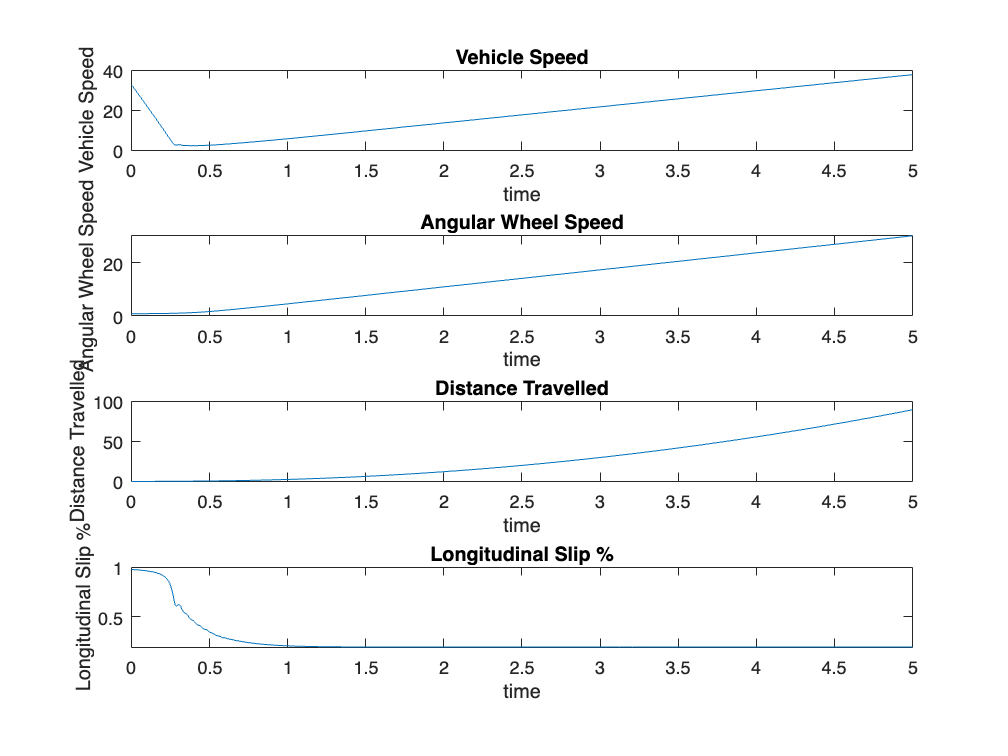

%Why is yout 3 in width? 
ynames=["Vehicle Speed","Angular Wheel Speed","Distance Travelled","Longitudinal Slip %"];
P = [yout slp]; %plots
for i = 1:1:4
    %figure(i)
    subplot(4,1,i)
    plot(t,P(:,i))
    xlabel('time')
    ylabel(ynames(i))
    title(ynames(i))
end 

# `7.Conclusions and future work`

`Overall, ABS and TCS can vary greatly with which models are used for tire forces, resulting in linear or nonlinear approximations. Beyond the model, the controller can be tuned and selected. `

`Further PID tuning and other tire models could be investigated. The goal of this document is to demonstrate the validity of the magic tire formula, and empiracle tire model and to implement manual tuning methods of PID's. `

# 8.Functions 

function plotABS(t,P)
ynames=["Vehicle Speed","Angular Wheel Speed","Stopping Distance","Slip %"];
for i = 1:1:4
    subplot(4,1,i),plot(t,P(:,i)),xlabel('time'),ylabel(ynames(i)),title(ynames(i))
end 
end 